# problem set 2

## Problem 1: persistence of excitation

1)    $R_{u\;} \left(0:3+4*k\right)=\left\lbrace 1,0,-1,0\right\rbrace \;$$\textrm{thus}\;p\ldotp e\ldotp \textrm{of}\;\textrm{order}\;2<4,\textrm{and}\;\textrm{therefor}\;\textrm{not}\;\textrm{sufficient}$

2)    the $\Phi_u$ must have contributions in at least $n_f +n_b =4$ locations, a sinusoid has contribution in 2 locations for each frequency, so $k=2$ should be sufficient assuming $\omega_i \not= \omega_j \;\forall \;i\not= j$

## Problem 2: noise estimate

signal to noise ratio := $\frac{\left|\right|y\left|\right|}{\left|\right|v\left|\right|}=\frac{1}{2\pi }\int_{-\pi }^{\pi } \frac{\hat{G} \left(e^{i\omega } \right)\Phi_u \left(\omega \right)}{\hat{H} \left(e^{i\omega } \right)\sigma_{\epsilon }^2 }d\omega$

## Problem 4: computer exercise

1) $n_f +n_b =6$, so the input should have at least a p.e. of order 6

2) to guarantee $S\in M$choose OE model with $\left\lbrace n_a ,n_b ,n_c ,{n_d ,n_f ,\;n}_k \right\rbrace =\left\lbrace 0,2,0,0,4,3\right\rbrace$

3) yes, because the input is persistently exciting and the model is in the model set

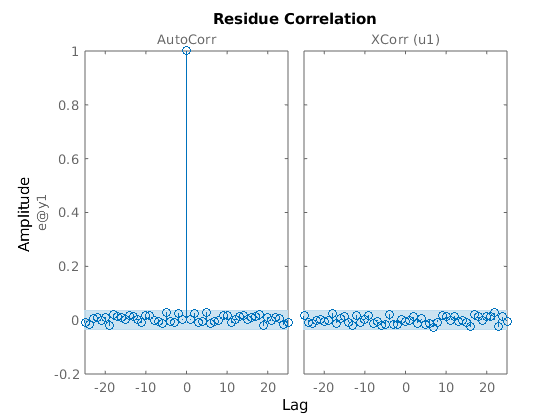

load("dataG0oe.mat");
data = iddata(y,u,1);
nb = 2;
nf = 4;
nk = 3;
sys_oe = oe(data, [nb nf nk]);
resid(data,sys_oe)

4) the residuals validate both H and G, and thus confirm the conclusions of item 3

5) No, since the system is not in the model set

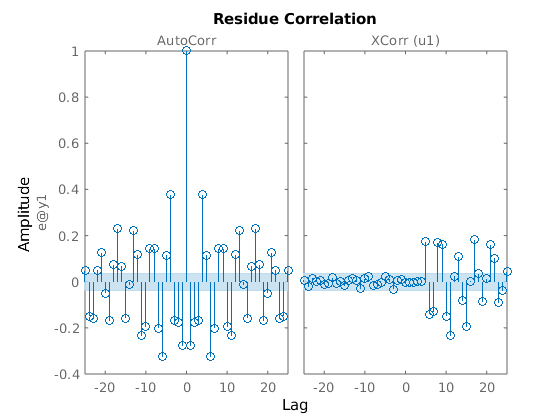

%%ARX model
na = 4;
nb = 2;
nk = 3;
sys_arx = arx(data,[na nb nk]);
resid(data,sys_arx)

6) the residuals invalidate both G and H, confirming the conclusions of item 5

comparison

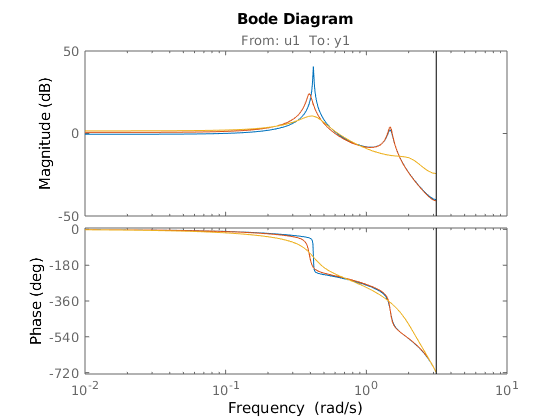

G0 = tf([0.10276 0.18123],[1 -1.99185 2.20265 -1.80483 0.89413],1);
bode(G0,sys_oe,sys_arx)

7) The bode confirms the statements, since the OE fitted model(red) is a relatively close match to the original(blue), where the ARX fitted model(yellow) is not.